# Lab 4: Working with 'real' data

## Introduction

In this lab we are going to work on how to estimate the background from 'real' data. Real is in air quotes because the data is actually from simplified simulations to make the problems manageable in a single lab. But the data will have *some* features that resemble that of real data sets.

## Getting data and HD5

In general exchanging raw data is a pain. Writing data in text files is error prone, inaccurate, and wastes space, but raw binary files have all sorts of subtleties too (including the internal byte order of your processor). To try and sidestep a whole set of nasty issues, we are going to use HDF5 (originally developed by the National Center for Supercomputing Applications for data exchange) to allow everyone to import the data. But this will require some additonal setup.

**MatLab**

In MatLab it is as usual a bit easier. First look at the file

`h5disp("gammaray_lab4.h5")`

Then import the data from the data 'directory' withing the hdf5 file

`mydata = h5read("gammaray_lab4.h5",'/data')`

and check you got the data imported (python and matlab have different row/column conventions)

`mydata(1,:)`

clc; clear; close all;
h5disp("gammaray_lab4.h5");

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata = h5read("gammaray_lab4.h5",'/data');
mydata(1,:);

## Problem 1

In this problem we are looking at the data from a gamma-ray satellite orbiting in low Earth orbit. It takes a reading of the number of particles detected every 100 milliseconds, and is in an approximately 90 minute orbit. While it is looking for gamma-ray bursts, virtually all of the particles detected are background cosmic rays.

As with most data, there are 'features.' Your lab instructor has helpfully incorporated the meta-data into your data file.

1) Down load the data from the course website (gammaray_lab4.h5), and import it into your working environment. The data has 4 columns and more than 25 million rows. The columns are time (in gps seconds), Solar phase (deg) showing the position of the sun relative to the orbit, Earth longitude (deg) giving the position of the spacecraft relative to the ground, and particle counts. Make a few plots, generally exploring your data and making sure you understand it. Give a high level description of the data features you see. Specifically comment on whether you see signal contamination in your data, and how you plan to build a background pdf().

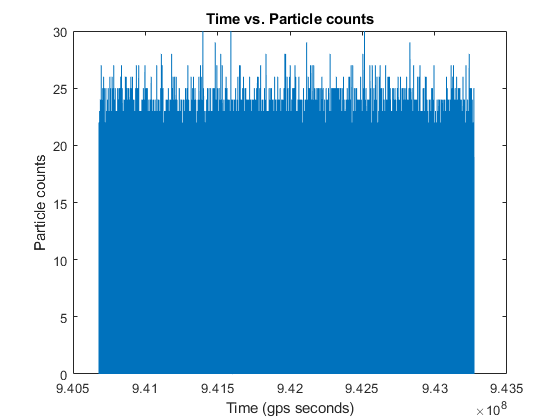

time = mydata(:,1);
Solar_phase = mydata(:,2);
Earth_longitude = mydata(:,3);
particle_counts = mydata(:,4);
figure;
plot(time,particle_counts);
title('Time vs. Particle counts');
xlabel('Time (gps seconds)');
ylabel('Particle counts');

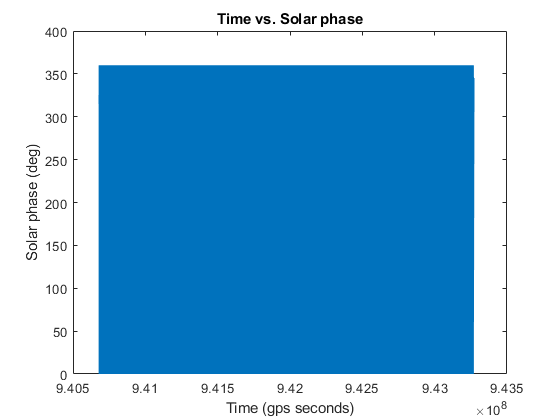

figure;
plot(time,Solar_phase);
title('Time vs. Solar phase');
xlabel('Time (gps seconds)');
ylabel('Solar phase (deg)');

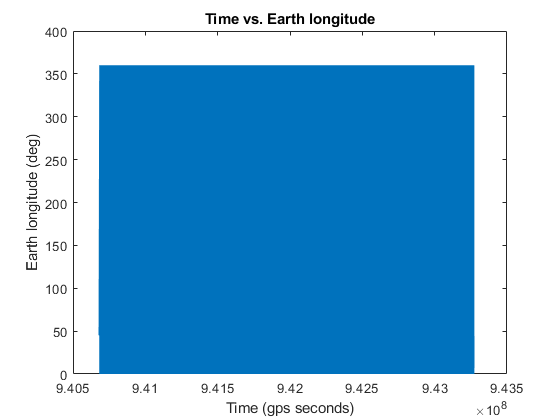

figure;
plot(time,Earth_longitude);
title('Time vs. Earth longitude');
xlabel('Time (gps seconds)');
ylabel('Earth longitude (deg)');

because the datasets holds very large datapoints, the graph it display with the times are unreadeable. We know the number of particles detected are every 100 milliseconds, and satellite is in an approximately 90 minute orbit. For one orbit will take approximately 5400000 milliseconds. Since the number of particles are only detected very 100 milliseconds, the the total number of times of the particle was detected is approximately 54000 times for one orbit. We will work with the time for 6 orbits to graph the datasets to check any patent.   

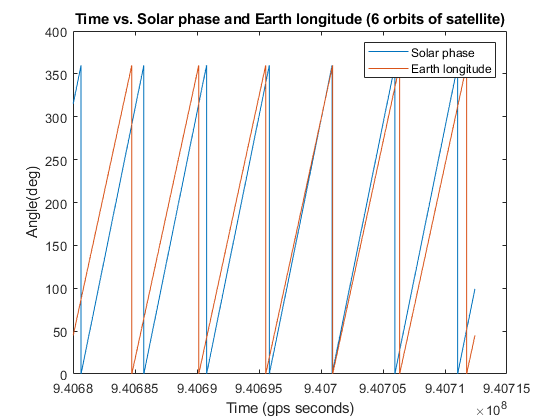

period = 54000;
orbits = 6;
figure;
plot(time(1:period*orbits),Solar_phase(1:period*orbits));
hold on;
plot(time(1:period*orbits),Earth_longitude(1:period*orbits));
title('Time vs. Solar phase and Earth longitude (6 orbits of satellite)');
xlabel('Time (gps seconds)');
ylabel('Angle(deg)');
legend('Solar phase', 'Earth longitude');

As show on Time vs. Solar phase and Earth longitude figure the datas are not random. There is consistent sawtooth wave pattern to Solar phase and Earth longitude related to time. The pattern make sense for the Solar phase because position of the sun relative to the orbit will vary between 0 to 360 degree. At a point when the position of the sun relative to the orbit reach to 360 degree. As the orbit moves the angle become 0 degree. That explain the sawtooth wave pattern. The pattern make sense for the Earth longitude because position of the spacecraft relative to the ground will vary between 0 to 360 degree as will.

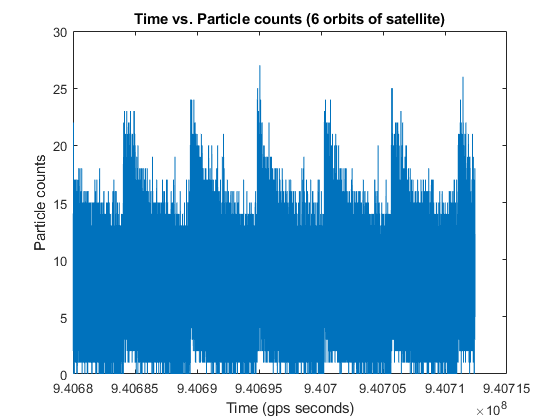

figure;
plot(time(1:period*orbits),particle_counts(1:period*orbits));
title('Time vs. Particle counts (6 orbits of satellite)');
xlabel('Time (gps seconds)');
ylabel('Particle counts');

As show on Time vs. Particle counts figure the datas are not random. There is jumps in the measurement correlate to the number of the orbits. Since the jumps appear to be periodic and the number of period is the same as the number of the orbits.The jump means there is affitional source of radiation at some point in the orbit. I think the jumps appear because the satellite exposure to radiation from the Sun. The decline of the particle counts because Earth blocks more and more of the Sun's radiation when satellite orbiting in low Earth orbit.

As show on Time vs. Particle counts figure the datas are discrete measurement. The distribution will be more likely to be discrete as well. The jumps looks like discrete independent events. That is why I chose Poisson distribution.

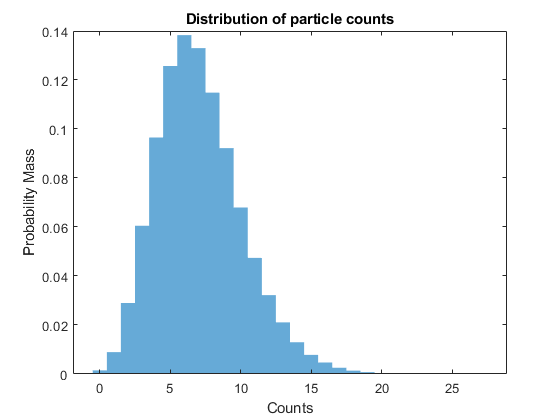

figure;
histogram(particle_counts(1:period*orbits),"Normalization","pdf","EdgeColor","none");
title('Distribution of particle counts');
xlabel('Counts');
ylabel('Probability Mass');

2) The background is **not** consistent across the dataset. Find and describe as accurately as you can how the background changes.

3) Create a model for the background that includes time dependence, and explicitly compare your model to the data. How good is your model of the background?

4) Because the background varies, your discovery sensitivity threshold (how many particles you would need to see) also varies. What is the '5-sigma' threshold for a 100 millisecond GRB at different times?

Optional: while this is simulated data, it is based on a real effect seen by low Earth orbit satellites. Can you identify the cause of the variable background and propose a physical model?

## Problem 2

In this problem we are going to look at a stack of telescope images (again simulated). We have 10 images, but you and your lab partner will be looking for different signals. One of you will be looking for the faintest stars, while the other will be looking for a transient (something like a super novae that only appears in one image). Flip a coin to determine which of you is pursuing which question.

1) Dowload the data from `images.h5`. This is a stack of 10 square images, each 200 pixels on a side.

2) Explore the data. Is there signal contamination? Is the background time dependent? Is it consistent spatially? Develop a plan to calculate your background pdf().

3) Using your background distribution, hunt for your signal (either faint stars, or a transient). Describe what you find.

4) You and your lab partner had different pdf(), but were using the *same* data. Explore why this is.